This code is a Finite Element Method (FEM) for solving the Poisson Equation in one dimension. It is based entirely off of this [tutorial](https://www.youtube.com/watch?v=igEMh5uTQk8&t=2050s). In particular, this code solves $\frac{\partial^2V}{\partial x^2}=f$, where $f$ is a constant, and with boundary condition on $V(0) $ and $V(d)$. It is solved over the domain $[0,d]$.

## Intitializations


clear
close all

N = 6; %number of elements
d = 12e-6; %we are sovling over the domain [0,d]
f = 1e10; %d2V/dx2 = f
Vl = -0.5; %left boundary condition V(0)
Vr = -0.6; %right boundary condition V(d)


## The Analytical Solution

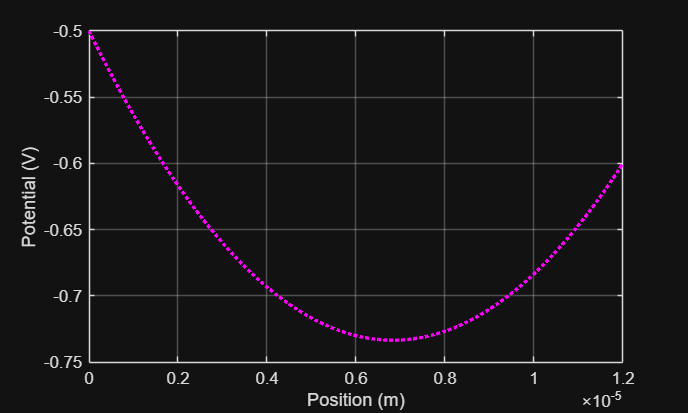

xa = linspace(0, d, 100); %defining our mesh domain for the analytical solution
Va = 0.5*f*xa.^2 + ((Vr-Vl)/d -0.5*f*d)*xa + Vl; %the analytical solution

%plotting the analytical solution
plot(xa, Va, ":m", 'LineWidth',2)
xlabel('Position (m)')
ylabel('Potential (V)')
grid on
hold on

## Numerical Solution with FEM

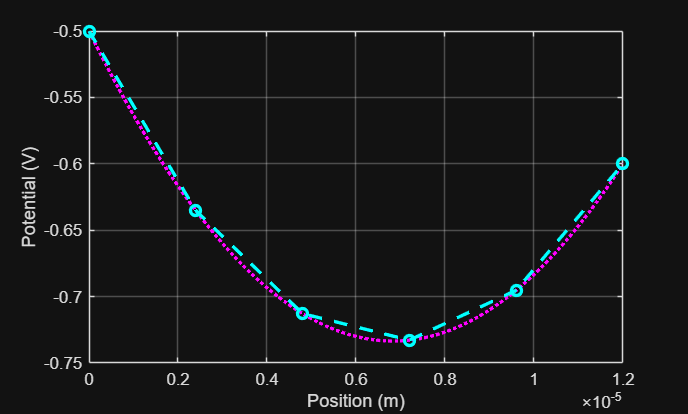

x = linspace(0,d,N); %defining our mesh domain
h(1:N-1) = x(2:N) - x(1:N-1); %defining element lengths

M = zeros(N-2, N-2); %initializing the ___ matrix

%defining the M matrix
M(1,1) = -1/h(1) - 1/h(2);
for i = 2:N-2
    M(i,i) = -1/h(i) - 1/h(i+1);
    M(i,i-1) = 1/h(i);
    M(i-1,i) = 1/h(i);
end

RHS = zeros(N-2,1); %initializing the RHS matrix

%defining RHS
for i = 1:N-2
    RHS(i) = 0.5*f*(h(i) + h(i+1));
end

RHSB = zeros(N-2,1); %initializing the RHSB matrix which represents the boundary conditions

%defining RHSB
RHSB(1) = -Vl/h(1);
RHSB(end) = -Vr/h(end);

VNc = M\(RHS+RHSB); %numerical solution in the central part of hte matrix

VN = zeros(N,1);
VN(1) = Vl; %enforcing left BC
VN(end) = Vr; %enforcing right BC

for i = 1:N-2
    VN(i+1) = VNc(i);
end

%plotting the numerical solution against the analytical one
plot(x, VN, "c--o", 'LineWidth',2)